# Cvičení 5 - B2M31AEDA

## Nahrání dat

Dejte si pozor na to, aby jste byli v MATLABu ve složce, kde máte umístěn soubor s daty (data.csv), nebo máte složku, ve které je soubor s daty, přidanou do cesty MATLABu (Matlab Path).

close all; clear; clc; addpath(genpath(fullfile([pwd '\Uni' '\grad' '\AEDA' '\week05' '\sem'])))
T = readtable('data.csv','ReadVariableNames',true);

HC = removevars(T(ismember(T.group, 'HC'),:), {'group', 'UPDRS_III', 'UHDRS'});
PD = removevars(T(ismember(T.group, 'PD'),:), {'group', 'UHDRS'});
HD = removevars(T(ismember(T.group, 'HD'),:), {'group', 'UPDRS_III'});

## 1. Vizualizace dat

Vizualizaci proveďte s důrazem na čitelnost a přehlednost. Cílem je vidět co nejlépe případné rozdíly mezi skupinami. Doporučujeme využít zobrazení pomocí `boxplot` či `boxchart` a rozvržení grafů pomocí funkce `tiledlayout`.

**Vizualizaci proveďte pro všechny 4 měřené akustické parametry: RI, DVA, MPT a stdF0.**

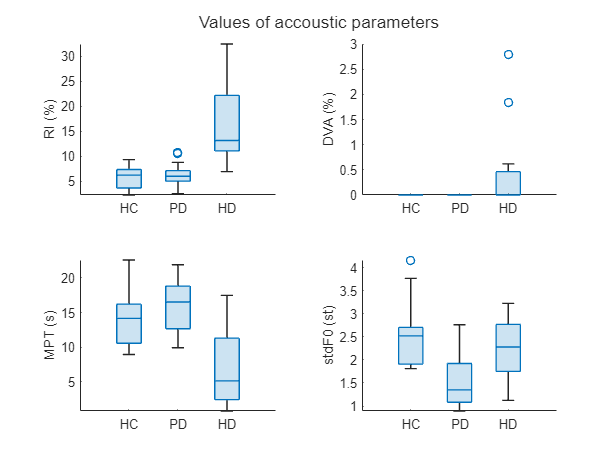

figure(1)
tiles = tiledlayout(2,2);

% Rhythm acceleration
nexttile
boxchart([HC.RI, PD.RI, HD.RI])
xticklabels({'HC', 'PD' 'HD'})
ylabel('RI (%)')
axis tight

% Degree of vocal arrest
nexttile
boxchart([HC.DVA, PD.DVA, HD.DVA])
xticklabels({'HC', 'PD' 'HD'})
ylabel('DVA (%)')
axis tight
ylim([0 3])     % discarding the far outlier

% Maximum phonation time
nexttile
boxchart([HC.MPT, PD.MPT, HD.MPT])
xticklabels({'HC', 'PD' 'HD'})
ylabel('MPT (s)')
axis tight

% Standard deviation of fundamental frequency
nexttile
boxchart([HC.stdF0, PD.stdF0, HD.stdF0])
xticklabels({'HC', 'PD' 'HD'})
ylabel('stdF0 (st)')
axis tight

title(tiles, 'Values of accoustic parameters')

**Otázky:**

- Pohledem vyhodnoťte jestli jednotlivé skupiny vykazují normální rozdělení (respektive  spíše pokud nějaká skupina vykazuje **významné odchylky od normálního rozdělení**) a zdali je mezi skupinami pro každý z parametrů vidět nějaký **efekt** (silný/slabý, či z hlediska pacienta pozitivní/negativní, …).

*Pouhým pohledem lze usoudit, nakolik je boxplot pro danou skupinu symetrický, což je typická charakteristika normálního rozdělení. Významně nesymetrický graf pozorujeme zejména v případě skupiny HC pro parametr stdF0 a v případě skupiny HD pro RI a MPT. Hodnota parametru DVA očividně nemá normální rozdělení ani pro jednu ze skupin.*

*Dále pozorujeme silný negativní efekt mezi skupinami subjektů netrpících a trpících HD pro parametry RI, DVA a MPT.*

## 2. Ověření podmínek pro ANOVA

### 2a Ověření Normality vstupních dat

- Vyberte vhodný test, viz předešlé cvičení a přednáška.

- Není třeba vypisovat hypotézy, pouze si dejte pozor – u jednotlivých testů se liší (viz např. rozdíl mezi `kstest` a `swtest`).

- Výsledky testu korektně reportujte.

alpha = 0.05;
samples = ["HC.RI", "HC.DVA", "HC.MPT", "HC.stdF0", ...
    "PD.RI", "PD.DVA", "PD.MPT", "PD.stdF0", ...
    "HD.RI", "HD.DVA", "HD.MPT", "HD.stdF0"];

for sample = samples
    if ~any(eval(sample))
        continue
    end

    [h, pValue, W] = swtest(eval(sample), alpha);

    if pValue < 0.001
        pReport = "p < 0.001";
    elseif pValue < 0.01
        pReport = sprintf('p = %.3f', pValue);
    else
        pReport = sprintf('p = %.2f', pValue);
    end

    if h == 0
        fprintf(['\tShapiro-Wilk test confirms that the null hypothesis of composite normality is a reasonable assumption\n' ...
            'regarding the population distribution of a random sample %s at significance level α = %.2f,\n' ...
            'W(%d) = %.4f, %s.\n\n'], ...
            sample, alpha, length(eval(sample))-1, W, pReport)
    else
        fprintf(['\tShapiro-Wilk test rejects the null hypothesis of composite normality regarding the population\n' ...
            'distribution of a random sample %s at significance level α = %.2f,\n' ...
            'W(%d) = %.4f, %s.\n\n'], ...
            sample, alpha, length(eval(sample))-1, W, pReport)
    end
end

	Shapiro-Wilk test confirms that the null hypothesis of composite normality is a reasonable assumption
regarding the population distribution of a random sample HC.RI at significance level α = 0.05,
W(14) = 0.9488, p = 0.51.

	Shapiro-Wilk test confirms that the null hypothesis of composite normality is a reasonable assumption
regarding the population distribution of a random sample HC.MPT at significance level α = 0.05,
W(14) = 0.9145, p = 0.16.



	Shapiro-Wilk test rejects the null hypothesis of composite normality regarding the population
distribution of a random sample HC.stdF0 at significance level α = 0.05,
W(14) = 0.8678, p = 0.03.



	Shapiro-Wilk test confirms that the null hypothesis of composite normality is a reasonable assumption
regarding the population distribution of a random sample PD.RI at significance level α = 0.05,
W(14) = 0.9230, p = 0.21.

	Shapiro-Wilk test confirms that the null hypothesis of composite normality is a reasonable assumption
regarding the population distribution of a random sample PD.MPT at significance level α = 0.05,
W(14) = 0.9500, p = 0.53.

	Shapiro-Wilk test confirms that the null hypothesis of composite normality is a reasonable assumption
regarding the population distribution of a random sample PD.stdF0 at significance level α = 0.05,
W(14) = 0.9040, p = 0.11.



	Shapiro-Wilk test rejects the null hypothesis of composite normality regarding the population
distribution of a random sample HD.RI at significance level α = 0.05,
W(14) = 0.8589, p = 0.02.

	Shapiro-Wilk test rejects the null hypothesis of composite normality regarding the population
distribution of a random sample HD.DVA at significance level α = 0.05,
W(14) = 0.3570, p < 0.001.

	Shapiro-Wilk test rejects the null hypothesis of composite normality regarding the population
distribution of a random sample HD.MPT at significance level α = 0.05,
W(14) = 0.8638, p = 0.03.



	Shapiro-Wilk test confirms that the null hypothesis of composite normality is a reasonable assumption
regarding the population distribution of a random sample HD.stdF0 at significance level α = 0.05,
W(14) = 0.9428, p = 0.42.



### 2b Oveření homogenity rozptylů

- **BUĎ: **Korektním způsobem argumentujte, proč lze požadavek na homogenitu rozptylů považovat za splněný i bez provádění testů. *Toto odůvodnění zapište slovy.*

- **NEBO: **Otestujte rovnost rozptylů pomocí vhodné analýzy – Bartlettova nebo Levenova testu. Výsledek testu korektně reportujte a interpretujte. Nápověda: funkce `vartestn`.

### **Reporty nebo odůvodnění:**

Požadavek homoskedasticity lze považovat za splněný i bez provádění testů díky tomu, že F-statistika využívaná v metodě ANOVA je obecně robustní vůči porušení tohoto předpokladu, pokud jsou zkoumané skupiny porovnatelné velikosti. V našem případě jsou velikosti skupin dokonce identické, a tak není třeba homoskedasticitu ověrovat (zdroj: [The Assumption of Homogeneity of Variance - Statistics Solutions](https://www.statisticssolutions.com/the-assumption-of-homogeneity-of-variance/)).

## 3. Úloha

Chtěli bychom dokázat, že lze rozlišit zdravé lidi (HC), pacienty s PD a pacienty s HD jen na základě nahrávek řečových testů, a případně i potvrdit, že změny v akustických parametrech úzce souvisí s celkovým klinickým hodnocením stavu pacienta.

**Použijte informace, které jste získali v předchozích částech, pro výběr vhodných testů a následnou interpretaci. Odpovězte na následující otázky:**

- *Lze mezi sebou statisticky významně rozlišit skupiny HC, PD a HD pomocí parametrů RI, MPT, DVA nebo stdF0? V této části hledáte jen odpověď ****ano či ne*** ***pomocí vhodného testu.***

- *Pokud jste zjistili, že pomocí nějakého parametru lze od sebe skupiny odlišit, ****jaké dvojice skupin vykazují mezi sebou statisticky významné rozdíly****?*

- *Jaký je ****vztah mezi zrychlováním řeči**** (parametr RI****) a klinickým hodnocením lékařem**** (hodnoty z dotazníků UPDRS a UHDRS)? Odpovídá horší schopnost udržet tempo řeči vyššímu motorickému postižení, hodnocenému lékařem?*

- Výběr statistických testů **odůvodněte**. 

- Pro opakované testy stačí zapsat testové hypotézy **jen jednou**.

- Reportujte výsledky testů **korektně** (využijte přednášku).

- Výsledky testů **interpretujte** s ohledem na předešlá rozhodnutí o normalitě, homoskedasticitě, výběru testu a výběru post-hoc metody.

#### Rozlišení skupin HC, PD a HD pomocí parametru RI

Pro parametr RI dopadly testy normality pozitivně v případě skupin HC a PD, přičemž v případě HD došlo k zamítnutí na základě toho, že $p=0\ldotp 02<0\ldotp 05=\alpha$, což lze považovat za nízkou míru neparametričnosti/nenormality dat. Požadavky homoskedasticity a nezávislosti jsou splněny automaticky, a proto lze s jistou rezervou využít metody ANOVA.

- Použitý test: ANOVA

- Nulová hypotéza: Všechny tři skupiny pochází z populací o stejné střední hodnotě.

- Alternativní hypotéza: Alespoň jedna ze tří testovaných skupin pochází z populace o střední hodnotě líšící se od ostatních.

fprintf(['The following study compares the effects of patient''s health condition on their RI (rhythm acceleration)\n' ...
    'performance. We inspected three subject groups (n = 15 per group):\n' ...
    '\tHealthy patients (M = %.2f, SD = %.2f).\n' ...
    '\tPatients affected by Parkinson''s disease (M = %.2f, SD = %.2f).\n' ...
    '\tPatients affected by Huntington''s disease (M = %.2f, SD = %.2f).\n' ...
    'We conducted a one-way ANOVA to compare the means of the three groups.'], ...
    mean(HC.RI), std(HC.RI), mean(PD.RI), std(PD.RI), mean(HD.RI), std(HD.RI))

The following study compares the effects of patient's health condition on their RI (rhythm acceleration)
performance. We inspected three subject groups (n = 15 per group):
	Healthy patients (M = 5.75, SD = 2.31).
	Patients affected by Parkinson's disease (M = 6.38, SD = 2.21).
	Patients affected by Huntington's disease (M = 17.13, SD = 8.40).
We conducted a one-way ANOVA to compare the means of the three groups.

[p, tbl, stats] = anova1([HC.RI, PD.RI, HD.RI], {'HC', 'PD', 'HD'}, "off");
assert(p < 0.001)
fprintf(['A one-way ANOVA revealed a statistically significant effect of subject''s condition on their RI ' ...
    'performance,\n' ...
    'F(%d,%d) = %.1f, p < 0.001. The effect size, eta squared (η²), was %.2f, indicating a large effect.'], ...
    tbl{2,3}, tbl{3,3}, tbl{2,5}, tbl{2,2}/tbl{4,2})

A one-way ANOVA revealed a statistically significant effect of subject's condition on their RI performance,
F(2,42) = 22.8, p < 0.001. The effect size, eta squared (η²), was 0.52, indicating a large effect.

c = multcompare(stats, 'CriticalValueType', 'bonferroni', 'Alpha', alpha, 'Display', 'off');
assert(all([c(2,6), c(3,6)] < 0.001))
fprintf(['Bonferroni''s post hoc test showed the subject group HD affected by Huntingtion''s disease scored\n' ...
    'significantly higher than both unaffected subject groups HC and PD, p < 0.001.'])

Bonferroni's post hoc test showed the subject group HD affected by Huntingtion's disease scored
significantly higher than both unaffected subject groups HC and PD, p < 0.001.

#### Rozlišení skupin HC, PD a HD pomocí parametru DVA

Parametr DVA jasně rozděluje subjekty na skupinu HD a skupinu HC+PD, a dokazuje tak statisticky významný efekt postižení Huntingtonovou nemocí na výsledek měření parametru DVA.

- Použitý test: selský rozum :)

#### Rozlišení skupin HC, PD a HD pomocí parametru MPT

Pro parametr MPT dopadly testy normality pozitivně v případě skupin HC a PD, přičemž v případě HD došlo k zamítnutí na základě toho, že $p=0\ldotp 03<0\ldotp 05=\alpha$, což lze považovat za nízkou míru neparametričnosti/nenormality dat. Požadavky homoskedasticity a nezávislosti jsou splněny automaticky, a proto lze s jistou rezervou využít metody ANOVA.

- Použitý test: ANOVA

- Nulová hypotéza: Všechny tři skupiny pochází z populací o stejné střední hodnotě.

- Alternativní hypotéza: Alespoň jedna ze tří testovaných skupin pochází z populace o střední hodnotě líšící se od ostatních.

fprintf(['The following study compares the effects of patient''s health condition on their MPT (maximum ' ...
    'phonation time)\n' ...
    'performance. We inspected three subject groups (n = 15 per group):\n' ...
    '\tHealthy patients (M = %.2f, SD = %.2f).\n' ...
    '\tPatients affected by Parkinson''s disease (M = %.2f, SD = %.2f).\n' ...
    '\tPatients affected by Huntington''s disease (M = %.2f, SD = %.2f).\n' ...
    'We conducted a one-way ANOVA to compare the means of the three groups.'], ...
    mean(HC.MPT), std(HC.MPT), mean(PD.MPT), std(PD.MPT), mean(HD.MPT), std(HD.MPT))

The following study compares the effects of patient's health condition on their MPT (maximum phonation time)
performance. We inspected three subject groups (n = 15 per group):
	Healthy patients (M = 14.13, SD = 4.14).
	Patients affected by Parkinson's disease (M = 16.01, SD = 3.71).
	Patients affected by Huntington's disease (M = 6.66, SD = 5.49).
We conducted a one-way ANOVA to compare the means of the three groups.

[p, tbl, stats] = anova1([HC.MPT, PD.MPT, HD.MPT], {'HC', 'PD', 'HD'}, "off");
assert(p < 0.001)
fprintf(['A one-way ANOVA revealed a statistically significant effect of subject''s condition on their MPT performance,\n' ...
    'F(%d,%d) = %.1f, p < 0.001.\nThe effect size, eta squared (η²), was %.2f, indicating a large effect.'], ...
    tbl{2,3}, tbl{3,3}, tbl{2,5}, tbl{2,2}/tbl{4,2})

A one-way ANOVA revealed a statistically significant effect of subject's condition on their MPT performance,
F(2,42) = 18.0, p < 0.001.
The effect size, eta squared (η²), was 0.46, indicating a large effect.

c = multcompare(stats, 'CriticalValueType', 'bonferroni', 'Alpha', alpha, 'Display', 'off');
assert(all([c(2,6), c(3,6)] < 0.001))
fprintf(['Bonferroni''s post hoc test showed the subject group HD affected by Huntingtion''s disease scored\n' ...
    'significantly lower than both unaffected subject groups HC and PD, p < 0.001.'])

Bonferroni's post hoc test showed the subject group HD affected by Huntingtion's disease scored
significantly lower than both unaffected subject groups HC and PD, p < 0.001.

#### Rozlišení skupin HC, PD a HD pomocí parametru stdF0

Pro parametr stdF0 dopadly testy normality pozitivně v případě skupin PD a HD, přičemž v případě HC došlo k zamítnutí na základě toho, že $p=0\ldotp 03<0\ldotp 05=\alpha$, což lze považovat za nízkou míru neparametričnosti/nenormality dat. Požadavky homoskedasticity a nezávislosti jsou splněny automaticky, a proto lze s jistou rezervou využít metody ANOVA.

- Použitý test: ANOVA

- Nulová hypotéza: Všechny tři skupiny pochází z populací o stejné střední hodnotě.

- Alternativní hypotéza: Alespoň jedna ze tří testovaných skupin pochází z populace o střední hodnotě líšící se od ostatních.

fprintf(['The following study compares the effects of patient''s health condition on their stdF0 (standard deviation\n' ...
    'of fundamental frequency) performance. We inspected three subject groups (n = 15 per group):\n' ...
    '\tHealthy patients (M = %.2f, SD = %.2f).\n' ...
    '\tPatients affected by Parkinson''s disease (M = %.2f, SD = %.2f).\n' ...
    '\tPatients affected by Huntington''s disease (M = %.2f, SD = %.2f).\n' ...
    'We conducted a one-way ANOVA to compare the means of the three groups.'], ...
    mean(HC.stdF0), std(HC.stdF0), mean(PD.stdF0), std(PD.stdF0), mean(HD.stdF0), std(HD.stdF0))

The following study compares the effects of patient's health condition on their stdF0 (standard deviation
of fundamental frequency) performance. We inspected three subject groups (n = 15 per group):
	Healthy patients (M = 2.59, SD = 0.73).
	Patients affected by Parkinson's disease (M = 1.51, SD = 0.56).
	Patients affected by Huntington's disease (M = 2.21, SD = 0.68).
We conducted a one-way ANOVA to compare the means of the three groups.

[p, tbl, stats] = anova1([HC.stdF0, PD.stdF0, HD.stdF0], {'HC', 'PD', 'HD'}, "off");
assert(p < 0.001)
fprintf(['A one-way ANOVA revealed a statistically significant effect of subject''s condition on their stdF0 per-\n' ...
    'formance, F(%d,%d) = %.1f, p < 0.001. The effect size, eta squared (η²), was %.2f, indicating a large effect.'], ...
    tbl{2,3}, tbl{3,3}, tbl{2,5}, tbl{2,2}/tbl{4,2})

A one-way ANOVA revealed a statistically significant effect of subject's condition on their stdF0 per-
formance, F(2,42) = 10.3, p < 0.001. The effect size, eta squared (η²), was 0.33, indicating a large effect.

c = multcompare(stats, 'CriticalValueType', 'bonferroni', 'Alpha', alpha, 'Display', 'off');
assert(c(1,6) < 0.001)
assert(c(3,6) < 0.05)
fprintf(['Bonferroni''s post hoc test showed the subject group PD affected by Parkinson''s disease scored\n' ...
    'significantly lower than both unaffected subject groups HC and HD, p < 0.001 and p = %.3f respectively.'], ...
    c(3,6))

Bonferroni's post hoc test showed the subject group PD affected by Parkinson's disease scored
significantly lower than both unaffected subject groups HC and HD, p < 0.001 and p = 0.018 respectively.

#### V**ztah mezi zrychlováním řeči** RI** a klinickým hodnocením lékařem UPDRS III**

- Nulová hypotéza: Hodnoty RI pacienta odráží jeho UPDRS III skóre.

- Alternativní hypotéza: Hodnoty RI pacienta neodráží jeho UPDRS III skóre.

Nejprve je zapotřebí vyšetřit normalitu dat UPDRS III, abychom mohli aplikovat Pearsonův test korelace, k čemuž opět využijeme Shapiro-Wilkův test:

[~, pValue, W] = swtest(PD.UPDRS_III, alpha);
assert(h == 0)
fprintf(['\tShapiro-Wilk test confirms that the null hypothesis of composite normality is a reasonable assumption\n' ...
        'regarding the population distribution of a random sample PD.UPDRS_III at significance level α = %.2f,\n' ...
        'W(%d) = %.4f, p = %.2f.'], ...
        alpha, length(PD.UPDRS_III)-1, W, pValue)

	Shapiro-Wilk test confirms that the null hypothesis of composite normality is a reasonable assumption
regarding the population distribution of a random sample PD.UPDRS_III at significance level α = 0.05,
W(14) = 0.9527, p = 0.57.

Normalita hodnot RI pro pacienty postižené Parkinsonovou chorobou byla ověřena v rámci úlohy 2a.

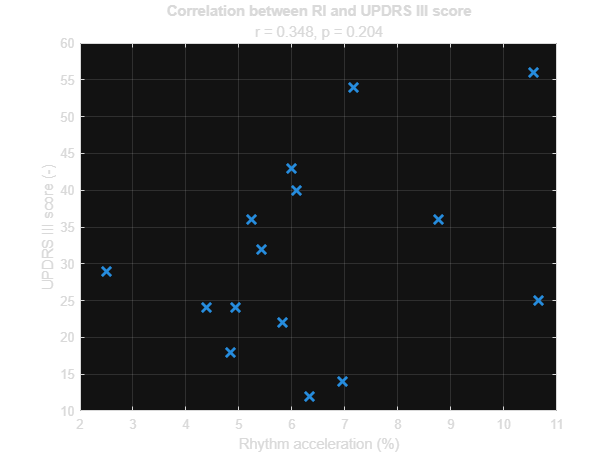

[r, p] = corr(PD.RI, PD.UPDRS_III, 'type', 'Pearson');

figure(2)
plot(PD.RI, PD.UPDRS_III, 'x', 'MarkerSize', 10, 'LineWidth', 2)
xlabel('Rhythm acceleration (%)')
ylabel('UPDRS III score (-)')
grid on
title('Correlation between RI and UPDRS III score')
subtitle(sprintf('r = %.3f, p = %.3f', r, p))

- Na základě Pearsonova testu korelace můžeme usoudit, že mezi hodnotami RI pacienta a jeho UPDRS III skóre existuje slabá korelace.

#### V**ztah mezi zrychlováním řeči** RI** a klinickým hodnocením lékařem UHDRS**

- Nulová hypotéza: Hodnoty RI pacienta odráží jeho UHDRS skóre.

- Alternativní hypotéza: Hodnoty RI pacienta neodráží jeho UHDRS skóre.

Nejprve je zapotřebí vyšetřit normalitu dat UHDRS, abychom mohli aplikovat Pearsonův test korelace, k čemuž opět využijeme Shapiro-Wilkův test:

[h, pValue, W] = swtest(HD.UHDRS, alpha);
assert(h == 0)
fprintf(['\tShapiro-Wilk test confirms that the null hypothesis of composite normality is a reasonable assumption\n' ...
        'regarding the population distribution of a random sample HD.UHDRS at significance level α = %.2f,\n' ...
        'W(%d) = %.4f, p = %.2f.'], ...
        alpha, length(HD.UHDRS)-1, W, pValue)

	Shapiro-Wilk test confirms that the null hypothesis of composite normality is a reasonable assumption
regarding the population distribution of a random sample HD.UHDRS at significance level α = 0.05,
W(14) = 0.8884, p = 0.06.

Normalita hodnot RI pro pacienty postižené Huntingtonovou chorobou byla v rámci úlohy 2a zamítnuta s $p=0\ldotp 02<0\ldotp 05=\alpha$, což lze v našem malém vzorku považovat za nízkou míru neparametričnosti/nenormality.

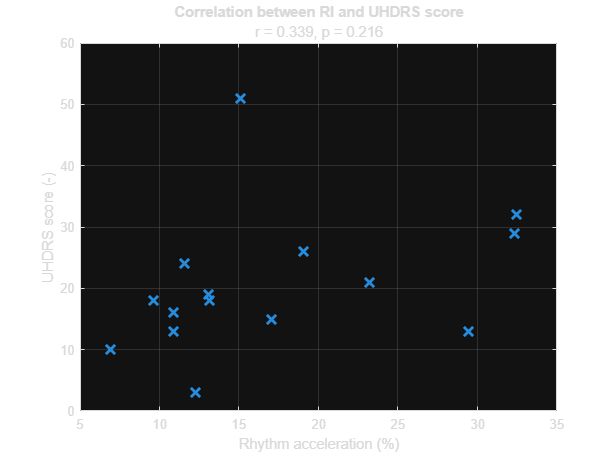

[r, p] = corr(HD.RI, HD.UHDRS, 'type', 'Pearson');

figure(3)
plot(HD.RI, HD.UHDRS, 'x', 'MarkerSize', 10, 'LineWidth', 2)
xlabel('Rhythm acceleration (%)')
ylabel('UHDRS score (-)')
grid on
title('Correlation between RI and UHDRS score')
subtitle(sprintf('r = %.3f, p = %.3f', r, p))

- Na základě Pearsonova testu korelace můžeme usoudit, že mezi hodnotami RI pacienta a jeho UHDRS skóre existuje slabá korelace.

### Nepovinný bonus

Manuálně implementujte jednosměrnou (one-way) ANOVA analýzu, a tu následně otestujte na vámi vygenerovaných datech (dvě přibližně normální rozdělení s vybraným efektem skupin).

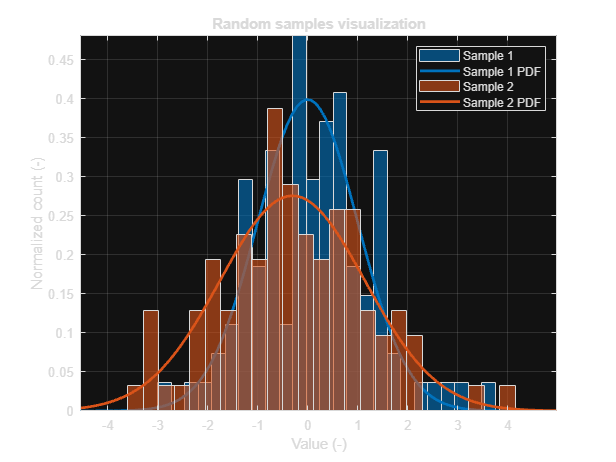

N = 100;                        % number of observations in a sample
effect = @(s) 1.2*s - 2;        % linear effect

sample1.mean = 0;
sample1.std = 1;
sample1.data = normrnd(sample1.mean, sample1.std, N, 1);

sample2.mean = sample1.mean + 1.5;
sample2.std = sample1.std + 0.2;
sample2.data = normrnd(sample2.mean, sample2.std, N, 1);
sample2.data = effect(sample2.data);
sample2.mean = mean(sample2.data);
sample2.std = std(sample2.data);

xRange = linspace(min([sample1.data; sample2.data])-1, max([sample1.data; sample2.data])+1);
nBins = 25;

figure(4)
hist1 = histogram(sample1.data, nBins, 'Normalization', 'pdf', 'FaceColor', '#0072BD');
hold on
plot(xRange, normpdf(xRange, sample1.mean, sample1.std), 'Color', hist1.FaceColor, 'LineWidth', 2)
hist2 = histogram(sample2.data, nBins, 'Normalization', 'pdf', 'FaceColor', '#D95319');
plot(xRange, normpdf(xRange, sample2.mean, sample2.std), 'Color', hist2.FaceColor, 'LineWidth', 2)
hold off
axis tight
grid on
xlabel('Value (-)')
ylabel('Normalized count (-)')
legend('Sample 1', 'Sample 1 PDF', 'Sample 2', 'Sample 2 PDF')
title('Random samples visualization')

Před tím, že začneme metodu implementovat, je třeba ověřit potřebné předpoklady ohledně vstupních dat:

- Normalita: Data jsou přesně vybrána z normální distribuce, viz vizualizace.

- Homoskedasticita: Mezi royptyly je minimální rozdíl a skupiny jsou stejné velikosti.

- Nezávislost: Data byla vygenerována nezávisle.

Some text about conduction of manual one-way ANOVA.

grand_mean = mean([sample1.data; sample2.data]);

SSC = N*((sample1.mean - grand_mean)^2 + (sample2.mean - grand_mean)^2);
[SSE, SST] = deal(0);
for i = 1:N
    SSE = SSE + (sample1.data(i) - sample1.mean)^2 + (sample2.data(i) - sample2.mean)^2;
    SST = SST + (sample1.data(i) - grand_mean)^2 + (sample2.data(i) - grand_mean)^2;
end
df_col = 2 - 1;
df_err = 2*N - 2;
df_tot = 2*N - 1;
MSC = SSC/df_col;
MSE = SSE/df_err;
F = MSC/MSE;
pValue = 1 - fcdf(F, df_col, df_err);
eta_sq = round(SSC/SST, 3);

if pValue < 0.001
    pReport = "p < 0.001";
elseif pValue < 0.01
    pReport = sprintf('p = %.3f', pValue);
else
    pReport = sprintf('p = %.2f', pValue);
end

if eta_sq <= 0.01
    effectSize = "small";
elseif eta_sq <= 0.059
    effectSize = "medium";
else
    effectSize = "large";
end

if pValue < 0.05
    fprintf(['A manually implemented one-way ANOVA revealed a statistically significant effect between studied\n' ...
        'sample groups 1 (M = %.2f, SD = %.2f) and 2 (M = %.2f, SD = %.2f), rejecting the null hypothesis that\n' ...
        'the groups come from normal distributions of equal means, F(%d,%d) = %.1f, %s.\n' ...
        'The effect size, eta squared (η²), was %.3f, indicating a %s effect.'], ...
        sample1.mean, sample1.std, sample2.mean, sample2.std, df_col, df_err, F, pReport, eta_sq, effectSize)
else
    fprintf(['A manually implemented one-way ANOVA didn''t reveal a statistically significant effect between studied\n' ...
        'sample groups 1 (M = %.2f, SD = %.2f) and 2 (M = %.2f, SD = %.2f), failing to reject the null hypothesis that\n' ...
        'the groups come from normal distributions of equal means, F(%d,%d) = %.1f, %s.\n' ...
        'The effect size, eta squared (η²), was %.3f, indicating a %s effect.'], ...
        sample1.mean, sample1.std, sample2.mean, sample2.std, df_col, df_err, F, pReport, eta_sq, effectSize)
end

A manually implemented one-way ANOVA didn't reveal a statistically significant effect between studied
sample groups 1 (M = 0.00, SD = 1.00) and 2 (M = -0.30, SD = 1.45), failing to reject the null hypothesis that
the groups come from normal distributions of equal means, F(1,198) = 3.1, p = 0.08.
The effect size, eta squared (η²), was 0.015, indicating a medium effect.